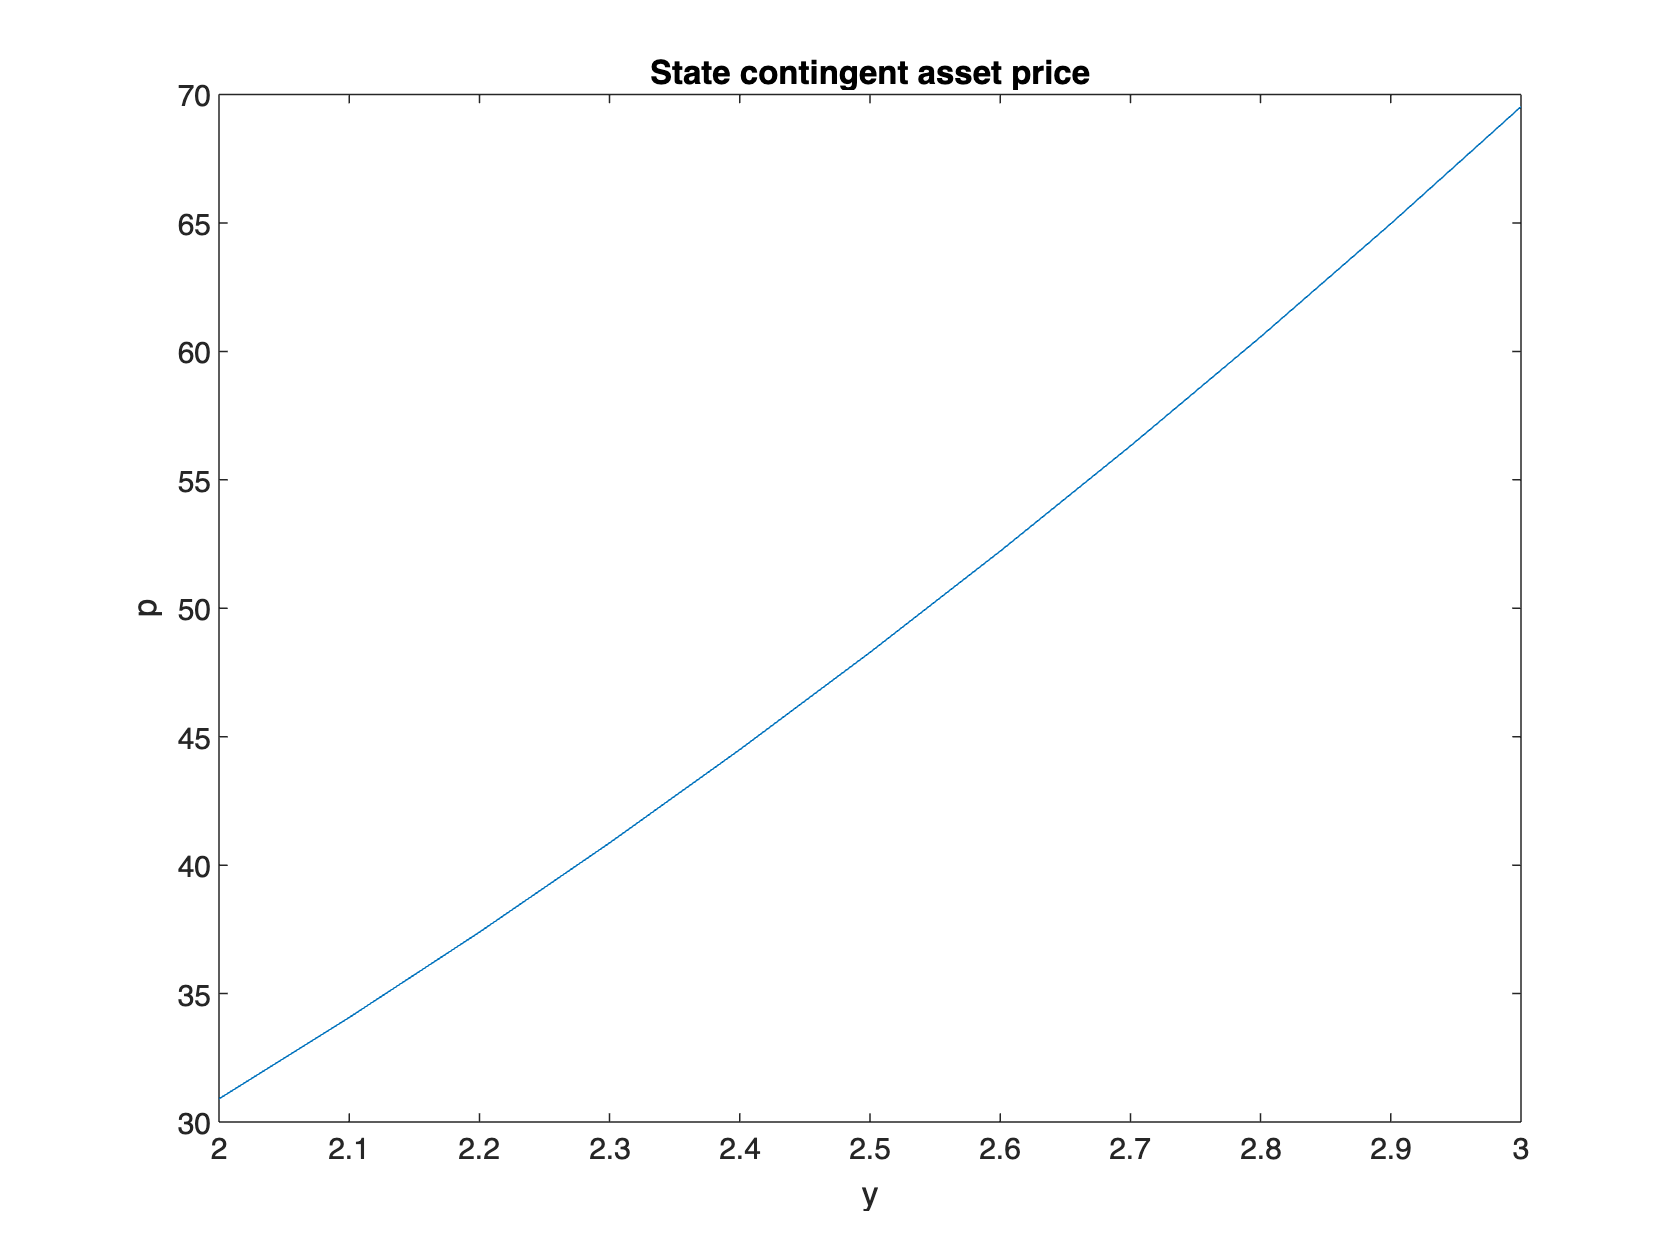

%% REPLICATION LUCAS ECTA 1978
%  Nicola Borri - nborri@luiss.it
%  First version: November 2016
%  Last update: September 2018

close all
clear
clc

%% Options

preferences = 0;
                    % 0 is CRRA
                    % 1 is Log utility
                    
transition  = 0;
                    % 0 is iid
                    % 1 is with persistence

%% Subjective time-discount factor

bet=0.95;

%% Dividends support
%% n possible outcomes, min is sig0, max is sig1 
n   = 11;
sig0=2;
sig1=3;
sig =linspace(sig0,sig1,n)';

savefiguredir = './figures/';
if exist(savefiguredir,'dir')==0
   mkdir(savefiguredir)
end

%% Transition probabilities

switch transition
    case 0  % Case 1: i.i.d. (each row sum up to 1)
        P=ones(n,n)*(1/n);
    case 1  % Case 2: persistence       
        P = NaN(n,n);
    for i=1:n
        for j=1:n
            if i==j
                P(i,j)=0.5; % 50% probability of staying in same state
            else
                P(i,j)=0.5/(n-1);
            end
        end
    end
end

%% Marginal utility

switch preferences
    case 0 % Case 1: CRRA
        gam=2;
        up=sig.^(-gam); % u prime (i.e., marginal utility)
        file_name  = './figures/P_CRRA';    
        file_name1 = './figures/term_CRRA';         
    case 1 % Case 2: log utility
        up=1./sig;    % u prime (i.e., marginal utility)
        file_name  = './figures/P_logU'; 
        file_name1 = './figures/term_logU';          
end

%% Solution of v=(I-bet*P)^(-1)*a
a = bet*(P*(sig.*up)); % a is column vector
%v = inv( eye(n) - bet*P  )*a;
v = (eye(n) - bet*P)\a; % use backslash for improved accuracy in matrix inversion in place of inv()
p = v./up;

figure('Name','State contingent asset price');
plot(sig,p);title('State contingent asset price');xlabel('y');ylabel('p');

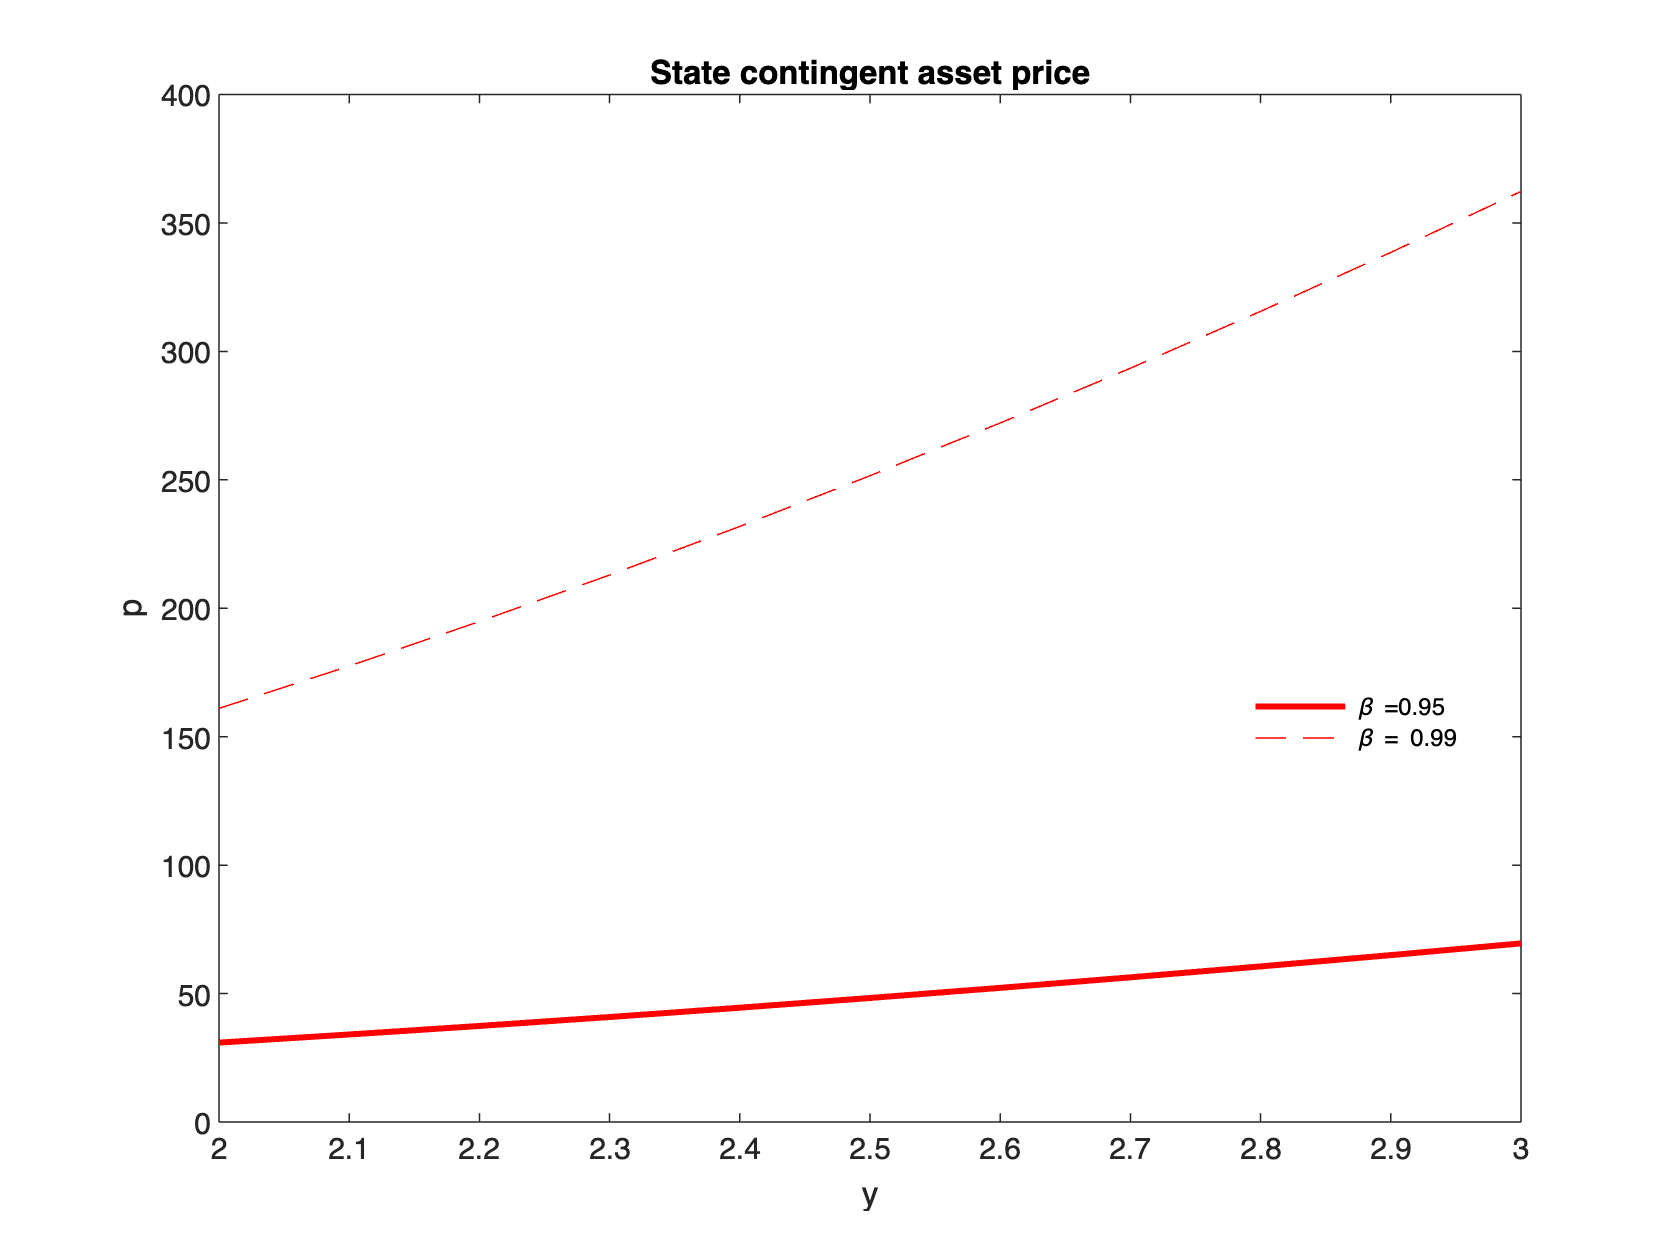


if preferences == 1 % if log u
    % Plot using perpetuity formula (for u = log)
    figure('Name','State contingent asset price (2)');
    plot(sig,sig*bet/(1-bet),'LineWidth',2,'Color','Red');
    hold on
    plot(sig,sig*0.99/(1-0.99),'--r')
    ylabel('p');xlabel('y');title('State contingent asset price')
    leg = legend(strcat('\beta = ',num2str(bet)),'\beta = 0.99','Location','Best');legend('boxoff')
    set(leg,'FontSize',8)
    hold off
end

% Re-do plot using function p_fun_lucas78 (see function for details)

figure('Name','State contingent asset price(3)');
plot(sig,p_fun_lucas78(bet,up,P,sig),'LineWidth',2,'Color','Red');
hold on
plot(sig,p_fun_lucas78(0.99,up,P,sig),'--r'); 
hold off
title('State contingent asset price');xlabel('y');ylabel('p')
leg = legend(strcat('\beta = ',num2str(bet)),'\beta = 0.99','Location','Best');legend('boxoff')
set(leg,'FontSize',8)
print('-depsc2',file_name);

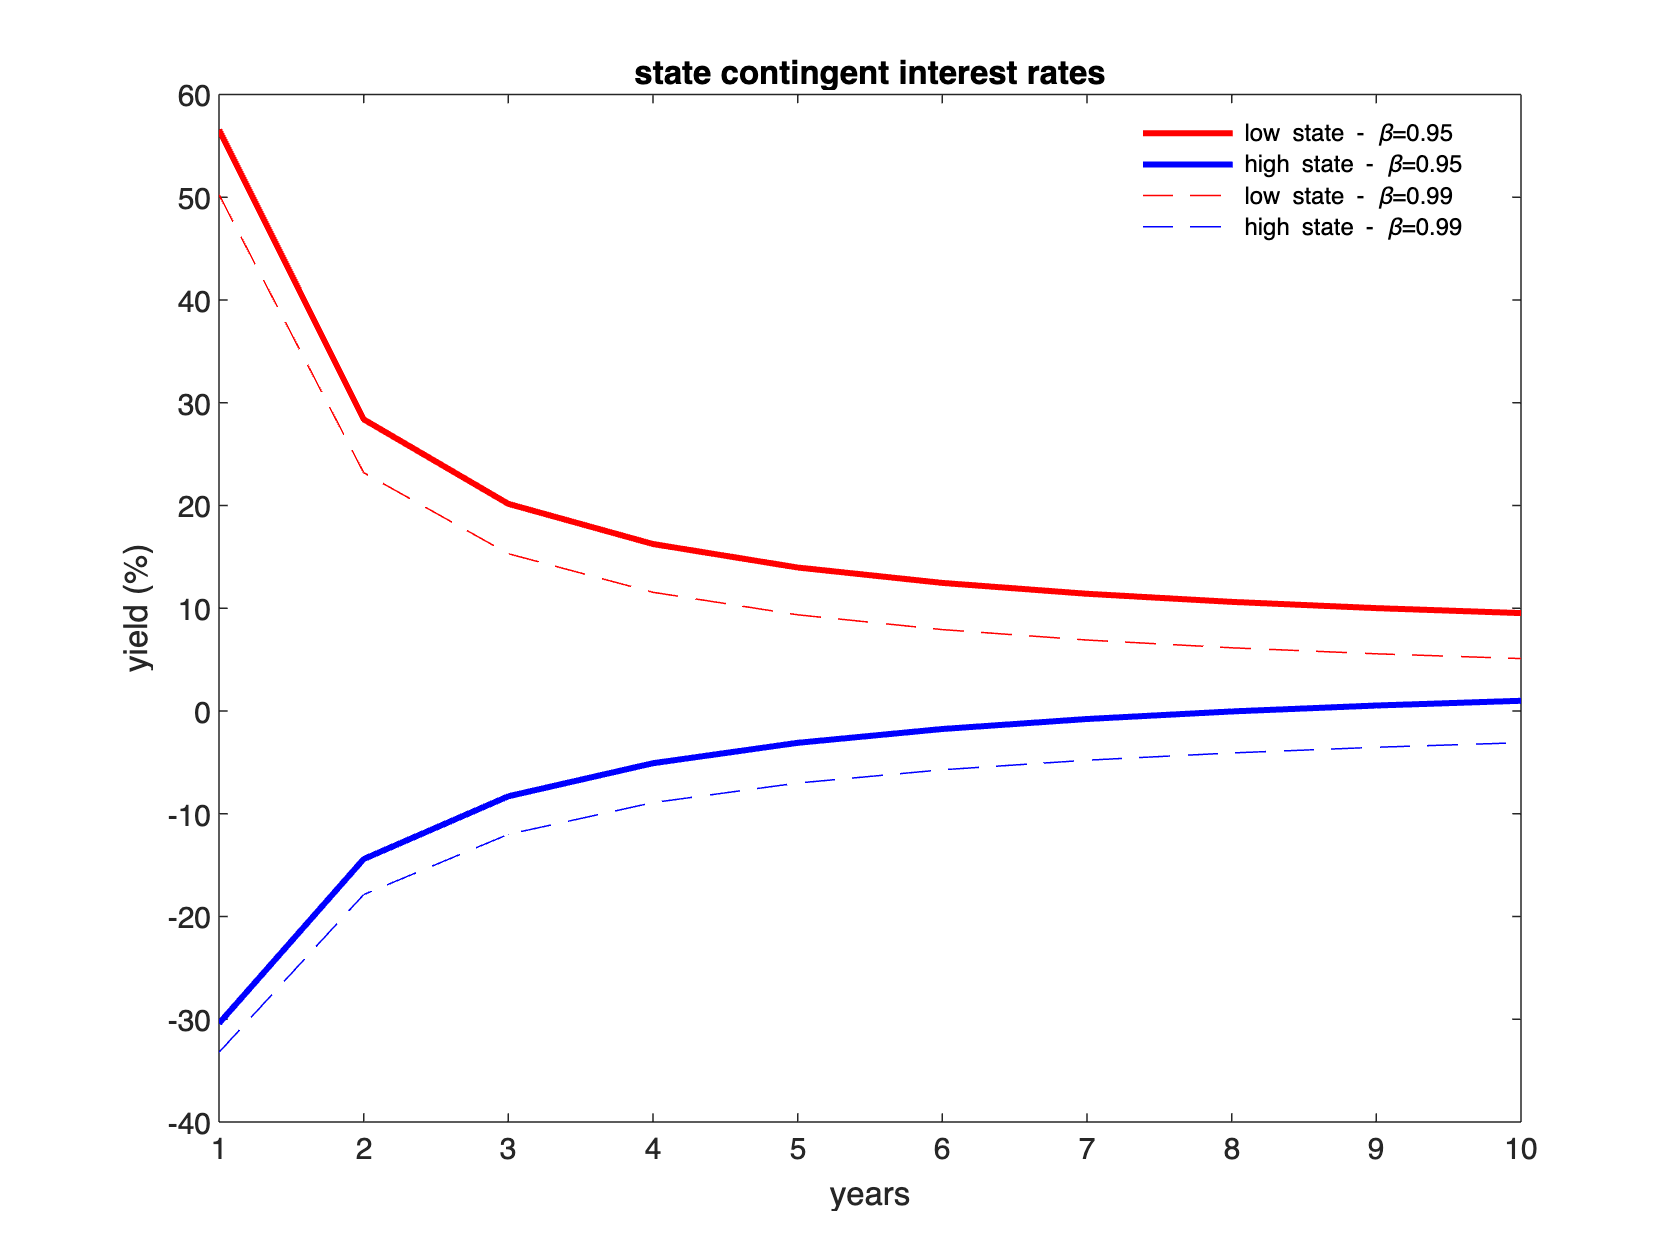


%% Price of a zero coupon bond with maturity 1

T          = 10;                 % max tenor
v_zcb      = NaN(length(sig),T); % storage
p_zcb      = NaN(length(sig),T); % storage
r_zcb      = NaN(length(sig),T); % storage

v_zcb(:,1) = bet* (P*up);        % P=E(M)
p_zcb(:,1) = v_zcb(:,1)./up;     % zero-coupon price
r_zcb(:,1) = 1./p_zcb(:,1);      % zero-coupon gross risk-free rate  

%% Term structure
for i=2:T % every col is different tenor, rows are states
    v_zcb(:,i) = bet* (P*v_zcb(:,i-1));
    p_zcb(:,i) = v_zcb(:,i)./up;
    r_zcb(:,i) = (1./p_zcb(:,i)).^(1/i);
end

figure('Name','Term structure of interest rates');
plot(1:1:T,100*(r_zcb(1,:)-1),'LineWidth',2,'Color','Red');
hold on;
r_temp = term_fun_lucas78(0.99,up,P,10);
plot(1:1:T,100*(r_zcb(end,:)-1),'r','LineWidth',2,'Color','Blue');
plot(1:1:T,100*(r_temp(1,:)-1),'--r');
plot(1:1:T,100*(r_temp(end,:)-1),'--b');
hold off;
xlabel('years');ylabel('yield (%)');title('state contingent interest rates');
leg = legend('low state - \beta=0.95','high state - \beta=0.95','low state - \beta=0.99','high state - \beta=0.99','Location','Best'); set(leg,'FontSize',8); legend('boxoff');
print('-depsc2',file_name1);